# Detect Outliers Using SVM and One-Class Learning

Modify Fisher's iris data set by assigning all the irises to the same class. Detect outliers in the modified data set, and confirm the expected proportion of the observations that are outliers.

Load Fisher's iris data set. Remove the petal lengths and widths. Treat all irises as coming from the same class.

load fisheriris
X = meas(:,1:2);
y = ones(size(X,1),1);

Train an SVM classifier using the modified data set. Assume that 5% of the observations are outliers. Standardize the predictors.

rng(1);
SVMModel_iris = fitcsvm(X,y,'Standardize',true,...
    'OutlierFraction',0.01);

`SVMModel` is a trained `ClassificationSVM` classifier. By default, the software uses the Gaussian kernel for one-class learning.

Plot the observations and the decision boundary. Flag the support vectors and potential outliers.

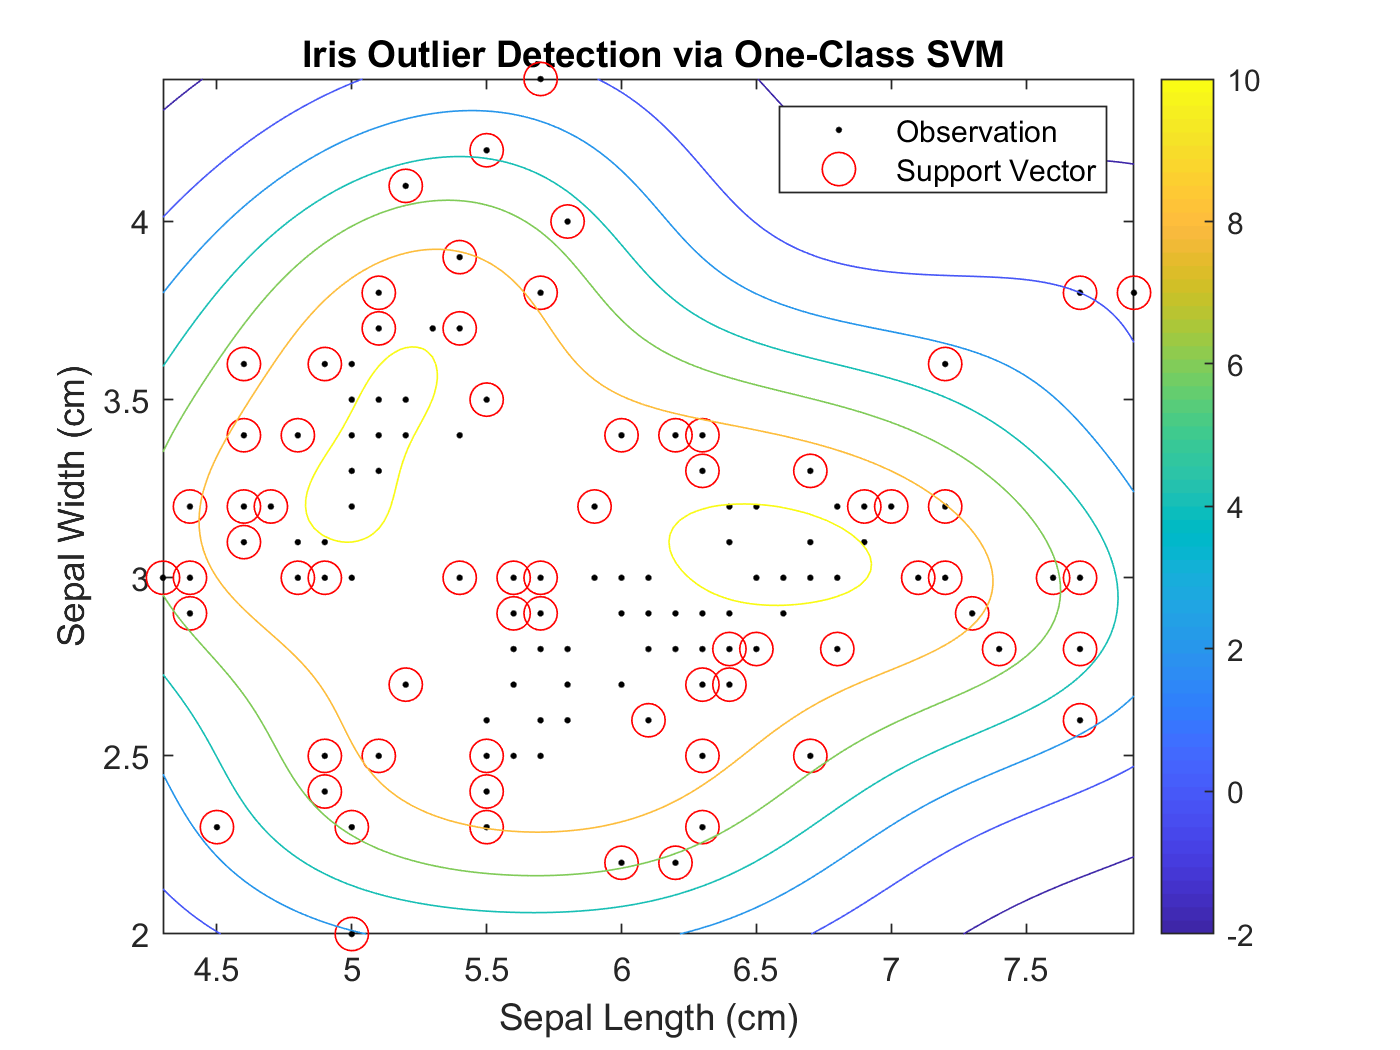

svInd = SVMModel_iris.IsSupportVector;
h = 0.02; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)),...
    min(X(:,2)):h:max(X(:,2)));
[~,score] = predict(SVMModel_iris,[X1(:),X2(:)]);
scoreGrid = reshape(score,size(X1,1),size(X2,2));

figure
plot(X(:,1),X(:,2),'k.')
hold on
plot(X(svInd,1),X(svInd,2),'ro','MarkerSize',10)
contour(X1,X2,scoreGrid)
colorbar;
title('{\bf Iris Outlier Detection via One-Class SVM}')
xlabel('Sepal Length (cm)')
ylabel('Sepal Width (cm)')
legend('Observation','Support Vector')
hold off

The boundary separating the outliers from the rest of the data occurs where the contour value is `0`.

Verify that the fraction of observations with negative scores in the cross-validated data is close to 5%.

CVSVMModel = crossval(SVMModel_iris);
[~,scorePred] = kfoldPredict(CVSVMModel);
outlierRate = mean(scorePred<0)

outlierRate = 0.0200

*Copyright 2015 The MathWorks, Inc.*